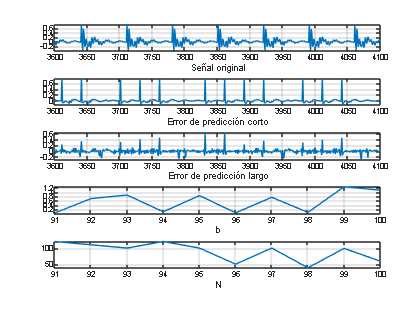

[x, ~] = audioread('test_period_70.wav');
% x_rec = x(4000:5000); 
[xr, error_pred_corto, error_pred_largo, delay, gain] = RPE_LTP_pulsos(x, 0);
% xr : señal reconstruida

% error_pred= x_rec-xr;
 snr_test = SNR(x,xr);           % Calculamos la snr del archivo test

% error_pred_corto = error_pred_corto(1600:2100);
% error_pred_largo = error_pred_largo(1600:2100);
figure(3)

% subplot 1: señal original
subplot(511)
plot((3600:4100), x(3600:4100))
xlabel('Señal original')
grid on
axis tight
xlim([3600, 4100])

% subplot 2: error de predicción corto
subplot(512)
plot((3600:4100), error_pred_corto(3600:4100))
xlabel('Error de predicción corto')
grid on
axis tight
xlim([3600, 4100])

% subplot 3: error de predicción largo
subplot(513)
plot((3600:4100), error_pred_largo(3600:4100))
xlabel('Error de predicción largo')
grid on
axis tight
xlim([3600, 4100])

% subplot 4: ganancia b
subplot(514)
plot((91:100), gain(91:100))
xlabel('b')
grid on
axis tight
xlim([91, 100])

% subplot 5: retardo N
subplot(515)
plot((91:100), delay(91:100))
xlabel('N')
grid on
axis tight
xlim([91, 100])


% figure(1)
% subplot(3, 1, 1); % Primera gráfica
% plot((4000:5000),x_rec);
% legend('señal orignal');
% xlabel('muestras');
% ylabel('amplitud');
% axis tight;
% 
% subplot(3,1,2);
% plot((4000:5000),xr);
% xlabel('muestras');
% ylabel('amplitud');
% legend('señal reconstruida');
% axis tight;
% 
% subplot(3,1,3);
% plot(error_pred,'g');
% ylabel('amplitud');
% legend('error de cuantificación');
% axis tight;
% sgtitle('test period 70.wav');

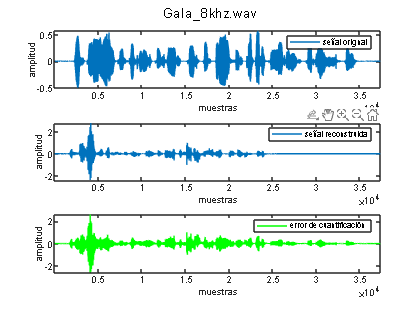

[x, ~] = audioread('Gala_8khz.wav');
[xr, ~, ~, ~, ~] = RPE_LTP_pulsos(x, 0);
% xr : señal reconstruida
snr_gala = SNR(x,xr);       % Calculamos la snr del archivo gala

error_pred = x-xr;
figure(2)
subplot(3, 1, 1); % Primera gráfica
plot(x);
legend('señal orignal');
xlabel('muestras');
ylabel('amplitud');
axis tight;

subplot(3,1,2);
plot(xr);
xlabel('muestras');
ylabel('amplitud');
legend('señal reconstruida');
axis tight;

subplot(3,1,3);
plot(error_pred,'g');
xlabel('muestras');
ylabel('amplitud');
legend('error de cuantificación');
axis tight;
sgtitle('Gala\_8khz.wav');

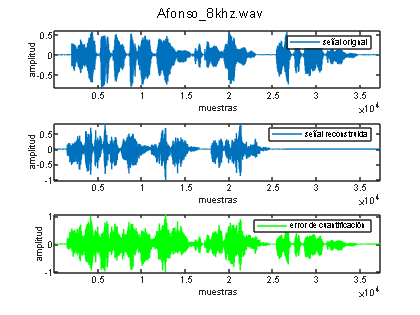

[x, ~] = audioread('Afonso_8khz.wav');
[xr, ~, ~, ~, ~] = RPE_LTP_pulsos(x, 0);
% xr : señal reconstruida
snr_afonso = SNR(x,xr);       % Calculamos la snr del archivo gala

error_pred = x-xr;
figure(2)
subplot(3, 1, 1); % Primera gráfica
plot(x);
legend('señal orignal');
xlabel('muestras');
ylabel('amplitud');
axis tight;

subplot(3,1,2);
plot(xr);
xlabel('muestras');
ylabel('amplitud');
legend('señal reconstruida');
axis tight;

subplot(3,1,3);
plot(error_pred,'g');
xlabel('muestras');
ylabel('amplitud');
legend('error de cuantificación');
axis tight;
sgtitle('Afonso\_8khz.wav');


save('SNR.mat', 'snr_gala', 'snr_afonso');



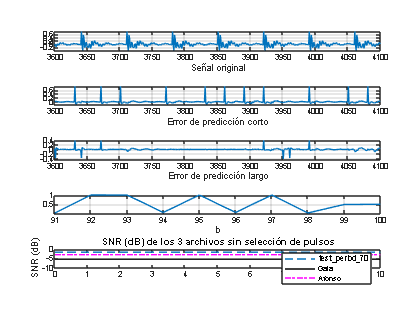

load('SNR.mat');
figure(3)

% Define nuevos valores de x en el rango de 0 a 10
x_values = linspace(0, 10, 10);

% Alarga los vectores repitiendo sus valores
snr_test_extended = repmat(snr_test, 1, ceil(length(x_values)/length(snr_test)));
snr_gala_extended = repmat(snr_gala, 1, ceil(length(x_values)/length(snr_gala)));
snr_afonso_extended = repmat(snr_afonso, 1, ceil(length(x_values)/length(snr_afonso)));

% Toma solo los primeros 10 valores
snr_test_extended = snr_test_extended(1:length(x_values));
snr_gala_extended = snr_gala_extended(1:length(x_values));
snr_afonso_extended = snr_afonso_extended(1:length(x_values));

% Grafica los resultados
plot(x_values, snr_test_extended, '--', x_values, snr_gala_extended, '-k', x_values, snr_afonso_extended, '-.m');
axis tight;
ylabel('SNR (dB)');
title('SNR (dB) de los 3 archivos sin selección de pulsos'); 
legend('test\_period\_70', 'Gala', 'Afonso');

% Ajusta el intervalo en el eje y
ylim([-10, 0]);